# Smart Cantilever Beam 1D Finite Element Model

Author: Febvre Maryne, 

Date: 04/2022 

Objective: This script models the dynamic behaviour of a cantilever beam using the one-dimensional finite element method (FEM). The beam has piezoelectric patches for sensing and actuation.

clc;
clear all;
clf;

Flag to save figures (set to 1 to save)

save_figure_var = 1; % 1 to save figure, 0 to not save

## Beam and Piezoelectric Transducers Properties

### Dimensions

Define the dimensions of the beam and piezoelectric patches (length, width, height)

L_beam = 0.105; % Total beam length (m)
l_beam = 0.052; % Beam width (m)
h_beam = 0.003; % Beam thickness (m)

L_piezo = 0.05; % Piezoelectric patch length (m)
l_piezo = 0.05; % Piezoelectric patch width (m)
h_piezo = 0.001; % Piezoelectric patch thickness (m)

L_pos = 0.005; % Position of piezoelectric patch from the beam end (m)

Number of piezoelectric transduceurs:

nb_patch = 2;

Vector of dimensions for easy access

dimensions = [L_beam, l_beam, h_beam, L_piezo, l_piezo, h_piezo, L_pos];

Create a figure to visualised the beam

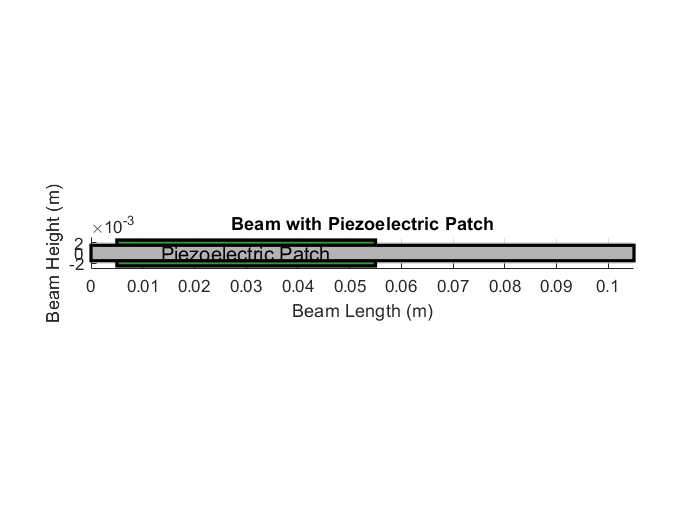

figure;
hold on;

% Plot the beam as a rectangle (in 2D view)
rectangle('Position', [0, -h_beam/2, L_beam, h_beam], 'FaceColor', [0.7, 0.7, 0.7], 'EdgeColor', 'k', 'LineWidth', 2);

% Plot the piezoelectric patch as a rectangle
rectangle('Position', [L_pos, h_beam/2, L_piezo, h_piezo], 'FaceColor', [0.2, 0.6, 0.2], 'EdgeColor', 'k', 'LineWidth', 2);
if nb_patch==2
    rectangle('Position', [L_pos, -h_beam/2-h_piezo, L_piezo, h_piezo], 'FaceColor', [0.2, 0.6, 0.2], 'EdgeColor', 'k', 'LineWidth', 2);
end
% Set axis properties
axis equal;
xlim([0, L_beam]);
ylim([-h_beam, h_beam]);
xlabel('Beam Length (m)');
ylabel('Beam Height (m)');
title('Beam with Piezoelectric Patch');

% Add labels for better understanding
text(L_pos + L_piezo/2, 0, 'Piezoelectric Patch', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontSize', 12);

% Display grid
grid on;
hold off;

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


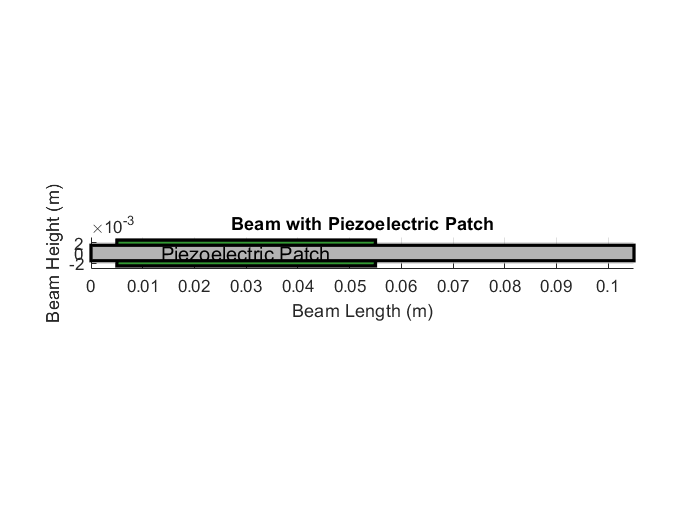

if save_figure_var == 1
    fig=gcf
    savefig('Figures/Piezo_Beam_scheme')
    save_fig_pdf('Figures/Piezo_Beam_scheme')
end

### Material Properties: Beam

Material: Aluminum (alternatively, use Steel AISI 4340)

Young Modulus [Pa]:

E_beam = 70e9; % For aluminum
% E_beam = 210e9; % Uncomment for steel

Density [kg/m^3]:

rho_beam = 2700; % For aluminum
% rho_beam = 7850; % Uncomment for steel

### Material Properties: Piezoelectric (PZ26 material)

Elastic Modulus (cE13) [Pa]:

E_piezo_13 = 10e+10;

Piezoelectric material density [kg/m^3]:

rho_piezo = 7700;

Piezoelectric coupling constant (Coulomb/m^2)

e13 = -2.8;

Relative Permittivity (at constant stress):

epsilon_0 = 8.854e-12; % Vacuum permittivity (F/m)
epsilon_33_S = 700 * epsilon_0; % Relative permittivity for PZ26 material
epsilon_33_T=1.33e3*epsilon_0;

Piezoelectric constant (C/N) [Coulomb/Newton]

d13 = e13 * 1 / E_piezo_13;

## Finite element model building

### Elementary Matrices

The finite element model is based on the folowing elementary matrix: 

Stifness: $K_{\textrm{elem}} =\frac{\textrm{EI}}{{\textrm{dL}}^3 }\left\lbrack  \begin{array}{cccc}12 & 6\textrm{dL} & -12 & 6\textrm{dL}\\6\textrm{dL} & 4{\textrm{dL}}^2   & -6\textrm{dL} & 2{\textrm{dL}}^2 \\-12 & -6\textrm{dL} & 12 & -6\textrm{dL}\\6\textrm{dL}  & 2{\textrm{dL}}^2  & -6\textrm{dL} & 4{\textrm{dL}}^2 \end{array}\right\rbrack  \;\;\;\;\;$; 

Mass : $M_{\textrm{elem}} =\frac{\rho \;h\;l\;\textrm{dL}}{420}\left\lbrack  \begin{array}{cccc}156 & 22\textrm{dL} & 54 & -13\textrm{dL}\\22\textrm{dL}  & 4{\textrm{dL}}^2  & 13\textrm{dL} & -3{\textrm{dL}}^2 \\54 & 13\textrm{dL}  & 156 & -22\textrm{dL}\\-13\textrm{dL} & -3{\textrm{dL}}^2  & -22\textrm{dL}  & 4{\textrm{dL}}^2 \end{array}\right\rbrack \;\;\;\;\;$; 

Inertia : $I=\frac{{l\;h}^3 }{12}$; 

Stiffness and mass matrices are defined according to beam-only (b) elements or piezo-beam (pb) elements.

Coupling Matrix:  ${\textrm{Kem}}_{\textrm{elem}} =e_{31} l_{\textrm{piezo}}  \frac{\left(h_{\textrm{piezo}} +h_{\textrm{beam}} \right)}{2}\left\lbrack \begin{array}{cccc}0  & -1 & 0 & 1\end{array}\right\rbrack$ and ${\textrm{Kme}}_{\textrm{elem}} =e_{31}  l_{\textrm{piezo}} \frac{\left(h_{\textrm{piezo}} +h_{\textrm{beam}} \right)}{2}\left\lbrack  \begin{array}{c}0\\-1\\0\\1\end{array}\right\rbrack$; 

Piezoelectric Capacity: $\textrm{Kee}=\frac{l_{\textrm{piezo}} h_{\textrm{piezo}}  }{h_{\textrm{piezo}} }\epsilon_{33}$

Number of finite elements in the beam:

Nb_element = 10;

Create elementary matrices:

[M_b_elem,K_b_elem,M_pb_elem, K_pb_elem, Kme_elem, Kem_elem, Kee , dL_beam] = create_elementary_matrices(dimensions, Nb_element, nb_patch, E_beam, rho_beam, E_piezo_13, rho_piezo, e13, epsilon_33_S)

M_b_elem =     0.0016    0.0000    0.0006   -0.0000
    0.0000    0.0000    0.0000   -0.0000
    0.0006    0.0000    0.0016   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000


K_b_elem = 1.0e+07 *

    8.4898    0.0446   -8.4898    0.0446
    0.0446    0.0003   -0.0446    0.0002
   -8.4898   -0.0446    8.4898   -0.0446
    0.0446    0.0002   -0.0446    0.0003


M_pb_elem =     0.0032    0.0000    0.0011   -0.0000
    0.0000    0.0000    0.0000   -0.0000
    0.0011    0.0000    0.0032   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000


K_pb_elem = 1.0e+08 *

    5.0818    0.0267   -5.0818    0.0267
    0.0267    0.0002   -0.0267    0.0001
   -5.0818   -0.0267    5.0818   -0.0267
    0.0267    0.0001   -0.0267    0.0002


Kme_elem = 1.0e-03 *

         0
    0.2800
         0
   -0.2800


Kem_elem = 1.0e-03 *

         0    0.2800         0   -0.2800


Kee = 3.0989e-10

dL_beam = 0.0105

% 

### Global Matrix Definition (M, K, G, etc.)

The global matrices are obtained by assembling the elementary matrices and applying the appropriate boundary condition to satisfy the following system of equations: 


$$M\left\lbrace \ddot{w} \right\rbrace +G\left\lbrace \dot{w} \right\rbrace +K\left\lbrace w\right\rbrace +K_{\mathrm{me}} \left\lbrace V\right\rbrace =F_{\mathrm{u2}} \left\lbrace F\right\rbrace$$



$$K_{\mathrm{em}} \left\lbrace w\right\rbrace -K_{\mathrm{ee}} \left\lbrace V\right\rbrace =-\left\lbrace q\right\rbrace$$


Assemble matrices and apply boundaries conditions:

[M, K, G, Nb_ddl, Kme, Kem, Kee] = create_FEM_beam(dimensions, 10, M_b_elem,K_b_elem,M_pb_elem, K_pb_elem, Kme_elem, Kem_elem, Kee, dL_beam); 

## Piezoelectric loading cases

### Short Circuit: V = 0, R = 0

In this case, the piezoelectric patch is shorted, meaning voltage (V) is zero, and resistance (R) is zero. This condition models the scenario where there is no electrical energy stored or dissipated.

$M\left\lbrace \ddot{w} \right\rbrace +G\left\lbrace \dot{w} \right\rbrace +K\left\lbrace w\right\rbrace =F_{\textrm{u2}} \left\lbrace F\right\rbrace$ --> $\begin{array}{l}
\dot{X} =\left\lbrack \begin{array}{cc}
0 & \mathrm{Id}\\
-M^{-1} K & -M^{-1} G
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & M^{-1} F_{\mathrm{u2}} 
\end{array}\right\rbrack U\\
Y=\left\lbrack \begin{array}{cc}
0 & 0\\
\mathrm{Id} & 0
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack U
\end{array}$

% Copy the original matrices (mass, stiffness, damping) for short circuit case
M_sc = M;
K_sc = K;
G_sc = G;

Define force vectors for state-space model (no external force applied for short circuit)

Fu1_sc = zeros(Nb_ddl - 2, 1);  % No force applied to the first degree of freedom
Fu2_sc = zeros(Nb_ddl - 2, 1);  % No force applied to the second degree of freedom
Fu2_sc(2) = 1;  % Apply force at the second degree of freedom

Define output matrices (no specific observation for short circuit)

Cd1_sc = zeros(Nb_ddl - 2, 1);  % No observation on the first degree of freedom
Cd2_sc = eye(Nb_ddl - 2);       % Observe all degrees of freedom except the first two
Dd_sc = 0;                       % No direct feedthrough

Create the state-space representation for the short circuit case

[Sys_sc, Asc, Bsc, Csc, Dsc, Nsc] = create_state_space(M_sc, G_sc, K_sc, Nb_ddl, Fu1_sc, Fu2_sc, Cd1_sc, Cd2_sc, Dd_sc);

Display the resulting state-space system for the short circuit case

Sys_sc

Sys_sc =
 
  A = 
                        w_{1}    \theta_{1}         w_{2}    \theta_{2}         w_{3}
   w_{1}                    0             0             0             0             0
   \theta_{1}               0             0             0             0             0
   w_{2}                    0             0             0             0             0
   \theta_{2}               0             0             0             0             0
   w_{3}                    0             0             0             0             0
   \theta_{3}               0             0             0             0             0
   w_{4}                    0             0             0             0             0
   \theta_{4}               0             0             0             0             0
   w_{5}                    0             0             0             0             0
   \theta_{5}               0             0             0             0             0
   w_{6}                    0       

### Open Circuit: q = 0, R = inf

In this case, the current (q) is zero, and resistance (R) is infinite. 

This models an open circuit scenario where there’s no current flow.

$M\left\lbrace \ddot{w} \right\rbrace +G\left\lbrace \dot{w} \right\rbrace +\left(K+K_{\textrm{me}} K_{\textrm{ee}}^{-1} K_{\textrm{em}} \right)\left\lbrace w\right\rbrace =F_{\textrm{u2}} \left\lbrace F\right\rbrace$ --> $\begin{array}{l}
\dot{X} =\left\lbrack \begin{array}{cc}
0 & \mathrm{Id}\\
-M^{-1} K_{\mathrm{eq}}  & -M^{-1} G
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & M^{-1} F_{\mathrm{u2}} 
\end{array}\right\rbrack U\\
Y=\left\lbrack \begin{array}{cc}
0 & 0\\
\mathrm{Id} & 0
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack U
\end{array}$

% Copy the original matrices for open circuit case
M_oc = M;
K_oc = K + Kme * inv(Kee) * Kem;  % Modify the stiffness matrix to include piezoelectric coupling
G_oc = G;

Define force vectors for state-space model (no external force applied for open circuit)

Fu1_oc = zeros(Nb_ddl - 2, 1);   % No force applied to the first degree of freedom
Fu2_oc = zeros(Nb_ddl - 2, 1);   % No force applied to the second degree of freedom
Fu2_oc(2) = 1;                    % Apply force at the second degree of freedom

Define output matrices (no specific observation for open circuit)

Cd1_oc = zeros(Nb_ddl - 2, 1);   % No observation on the first degree of freedom
Cd2_oc = eye(Nb_ddl - 2);        % Observe all degrees of freedom except the first two
Dd_oc = 0;                        % No direct feedthrough

Create the state-space representation for the open circuit case

[Sys_oc, Aoc, Boc, Coc, Doc, Noc] = create_state_space(M_oc, G_oc, K_oc, Nb_ddl, Fu1_oc, Fu2_oc, Cd1_oc, Cd2_oc, Dd_oc);

Display the resulting state-space system for the open circuit case

Sys_oc

Sys_oc =
 
  A = 
                        w_{1}    \theta_{1}         w_{2}    \theta_{2}         w_{3}
   w_{1}                    0             0             0             0             0
   \theta_{1}               0             0             0             0             0
   w_{2}                    0             0             0             0             0
   \theta_{2}               0             0             0             0             0
   w_{3}                    0             0             0             0             0
   \theta_{3}               0             0             0             0             0
   w_{4}                    0             0             0             0             0
   \theta_{4}               0             0             0             0             0
   w_{5}                    0             0             0             0             0
   \theta_{5}               0             0             0             0             0
   w_{6}                    0       

% 

### Resistive Shunt

In this case, a resistive shunt is placed across the piezoelectric patch.

The resistive element introduces dissipation in the system, which allows current flow.

$\begin{array}{l}
M\left\lbrace \ddot{w} \right\rbrace +G\left\lbrace \dot{w} \right\rbrace +K\left\lbrace w\right\rbrace +K_{\textrm{me}} \left\lbrace V\right\rbrace =F_{\textrm{u2}} \left\lbrace F\right\rbrace \\
K_{\textrm{em}} \left\lbrace w\right\rbrace -K_{\textrm{ee}} \left\lbrace V\right\rbrace =-\left\lbrace q\right\rbrace 
\end{array}$ --> $\begin{array}{l}
\dot{X} =\left\lbrack \begin{array}{cc}
0 & \mathrm{Id}\\
-M^{-1} K_{\mathrm{eq}}  & -M^{-1} G
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
0 & 0\\
-M^{-1} K_{\mathrm{me}}  & M^{-1} F_{\mathrm{u2}} 
\end{array}\right\rbrack U\\
Y=\left\lbrack \begin{array}{cc}
-K_{\mathrm{em}}  & 0\\
\mathrm{Id} & 0
\end{array}\right\rbrack X+\left\lbrack \begin{array}{cc}
K_{\mathrm{ee}}  & 0\\
0 & 0
\end{array}\right\rbrack U
\end{array}$

% Copy the original matrices for resistive shunt case
M_rs = M;
K_rs = K;
G_rs = G;

Define transfer function for resistive shunt (using zeros_values for system input)

zeros_values = zeros(1, Noc);
zeros_values(end - 1) = 1;  % Define the input to the system for resistive shunt
s = tf(zeros_values, [1]);  % Create transfer function with given zeros and denominator

Define force vectors for state-space model

Fu1_rs = Kme;  % Force applied due to the piezoelectric coupling
Fu2_rs = zeros(Nb_ddl - 2, 1);   % No force applied to the first degree of freedom
Fu2_rs(2) = -1;  % Apply force at the second degree of freedom (negative)
Fu2_rs(4) = 1;   % Apply force at the fourth degree of freedom (positive)

Define output matrices for resistive shunt case

Cd1_rs = -Kem';  % Output matrix related to the piezoelectric coupling (negative)
Cd2_rs = eye(Nb_ddl - 2);  % Observe all degrees of freedom except the first two
Dd_rs = Kee;   % Feedthrough term (related to piezoelectric capacitance)

Create the state-space representation for the resistive shunt case

[Sys_rs, Ars, Brs, Crs, Drs, Nrs] = create_state_space(M_rs, G_rs, K_rs, Nb_ddl, Fu1_rs, Fu2_rs, Cd1_rs, Cd2_rs, Dd_rs);

Display the resulting state-space system for the resistive shunt case

Sys_rs

Sys_rs =
 
  A = 
                        w_{1}    \theta_{1}         w_{2}    \theta_{2}         w_{3}
   w_{1}                    0             0             0             0             0
   \theta_{1}               0             0             0             0             0
   w_{2}                    0             0             0             0             0
   \theta_{2}               0             0             0             0             0
   w_{3}                    0             0             0             0             0
   \theta_{3}               0             0             0             0             0
   w_{4}                    0             0             0             0             0
   \theta_{4}               0             0             0             0             0
   w_{5}                    0             0             0             0             0
   \theta_{5}               0             0             0             0             0
   w_{6}                    0       

## Create Bode Plot

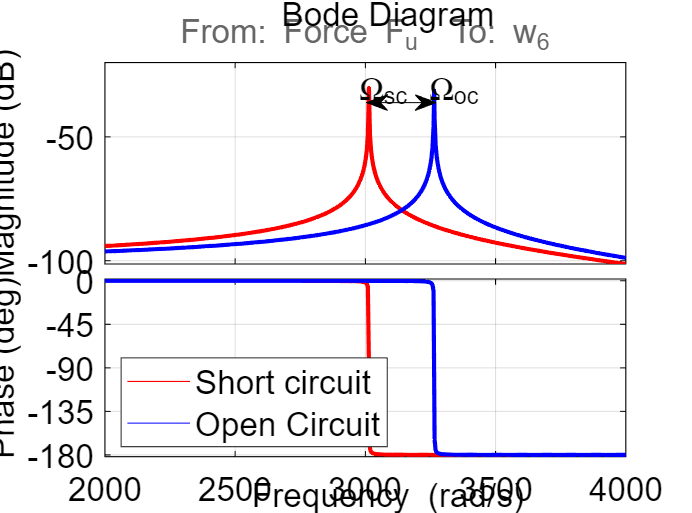


interval_plot = [2000:0.01:4000];  % Frequency interval for Bode plot

% Create figure for Bode plot
fig1 = figure;
g = bodeoptions;
g.FreqScale = 'Linear';
g.PhaseWrapping = 'on';
g.Grid = 'on';
g.XLim = {[2e3 4e3]};  % Frequency limits for the plot
fig1.Name = 'Bode plot';  % Name of the figure

% Plot Bode plot for short-circuit (Sys_sc) and open-circuit (Sys_oc) systems
bodeplot(Sys_sc(12, end), 'r', interval_plot, g);  % Short circuit in red
hold on;
bodeplot(Sys_oc(12, end), 'b', interval_plot, g);  % Open circuit in blue
legend('Short circuit', 'Open Circuit', 'Location', 'southwest');
hold off;

% Create arrows for annotation
annotation('arrow', [0.53 0.63], [0.8 0.8]);
annotation('arrow', [0.63 0.53], [0.8 0.8]);

% Create textboxes for annotation
annotation('textbox', [0.50 0.80 0.12 0.08], 'String', '\Omega_{sc}', 'FitBoxToText', 'off', 'EdgeColor', 'none');
annotation('textbox', [0.60 0.80 0.12 0.08], 'String', '\Omega_{oc}', 'FitBoxToText', 'off', 'EdgeColor', 'none');

fontsize(fig1, 16, "points")
fig1.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

fig =   Figure (4: Bode plot) with properties:

      Number: 4
        Name: 'Bode plot'
       Color: [1 1 1]
    Position: [100 100 1080 800]
       Units: 'pixels'

  Show all properties


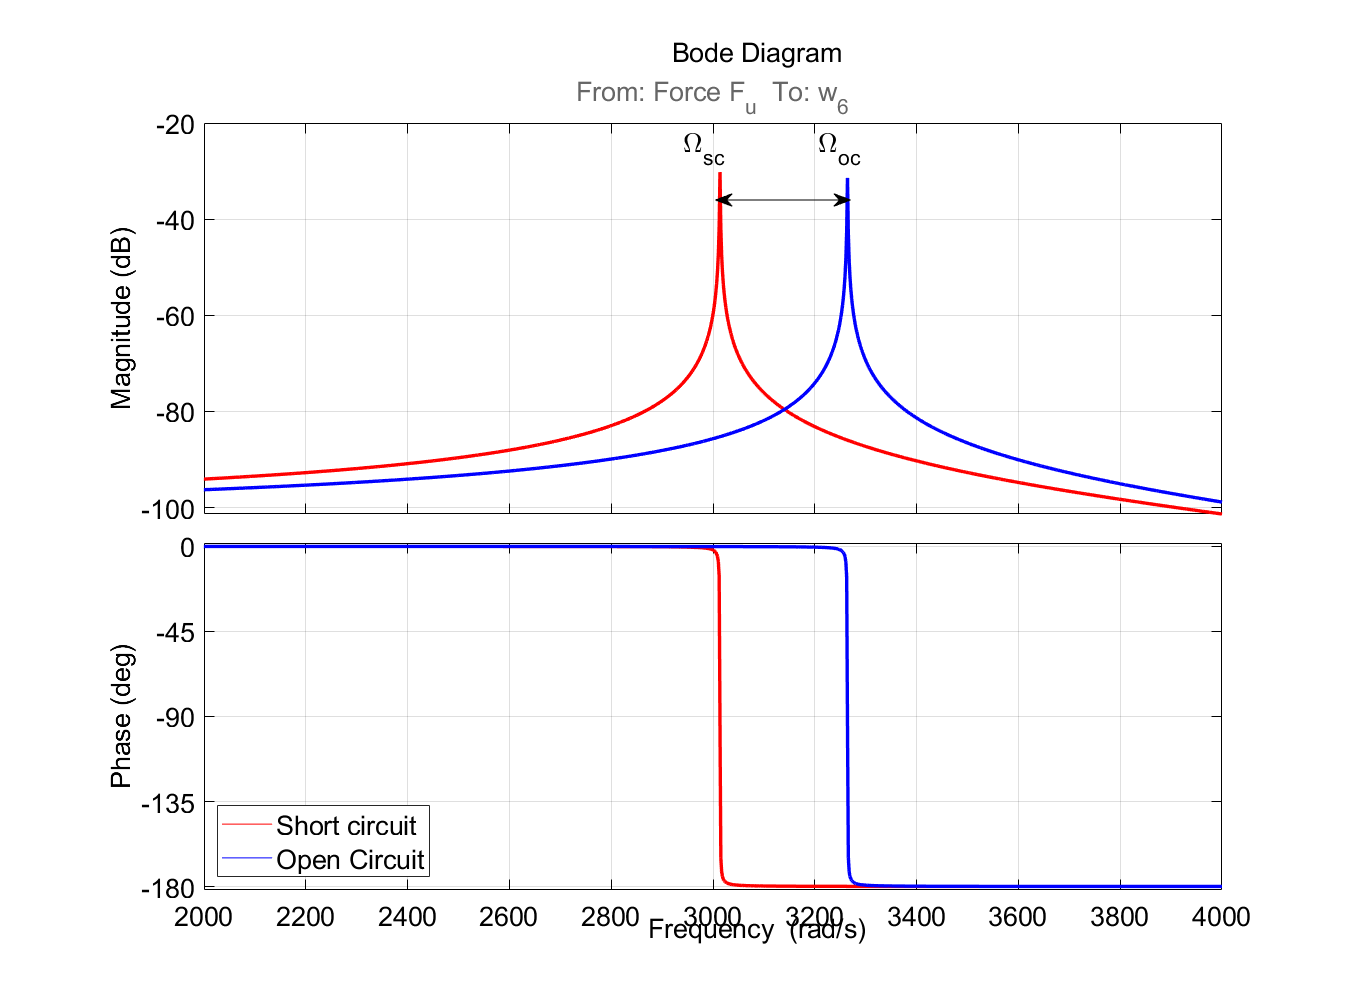

if save_figure_var == 1
    fig=gcf
    savefig('Figures/Bode_Sys_oc_sc')
    save_fig_pdf('Figures/Bode_Sys_oc_sc')
end


save('Datas/FEM_smart_beam')